Loading in the files

nearFieldPulse = load("C:\Users\vegar\MATLAB\ultralyd\assign4\NearFieldPulse.mat");
profile_AZ_7cm_full = load("C:\Users\vegar\MATLAB\ultralyd\assign4\profile_AZ_7cm_Full.mat");
profile_AZ_7cm_reduced = load("C:\Users\vegar\MATLAB\ultralyd\assign4\profile_AZ_7cm_reduced.mat");
profile_EL_7cm_full = load("C:\Users\vegar\MATLAB\ultralyd\assign4\profile_EL_7cm_Full.mat");
profile_EL_7cm_reduced = load("C:\Users\vegar\MATLAB\ultralyd\assign4\profile_EL_7cm_reduced.mat");
pulse_7cm_0dB_10x_aver = load("C:\Users\vegar\MATLAB\ultralyd\assign4\pulse_7cm_0dB_10x_aver.mat");
pulse_7cm_m8dB_10x_aver = load("C:\Users\vegar\MATLAB\ultralyd\assign4\pulse_7cm_-8dB_10x_aver.mat");
pulse_7cm_m14dB_10x_aver = load("C:\Users\vegar\MATLAB\ultralyd\assign4\pulse_7cm_-14dB_10x_aver.mat");
pulse_7cm_m14dB_no_aver = load("C:\Users\vegar\MATLAB\ultralyd\assign4\pulse_7cm_-14dB_no_aver.mat");
z_axis_12dB = load("C:\Users\vegar\MATLAB\ultralyd\assign4\z_axis_12dB.mat"); 

Fetching usefull information from the structs

pulse14_rf_noA = pulse_7cm_m14dB_no_aver.RF;
pulse14_rf_10A = pulse_7cm_m14dB_10x_aver.RF;
pulse8_rf_10A = pulse_7cm_m8dB_10x_aver.RF;
pulse0_rf_10A = pulse_7cm_m0dB_10x_aver.RF;

time_pulse14_noA = linspace(pulse_7cm_m14dB_no_aver.Time,size(pulse14_rf_noA),pulse_7cm_m14dB_no_aver.Ts)


Task 1 pulse in focus 

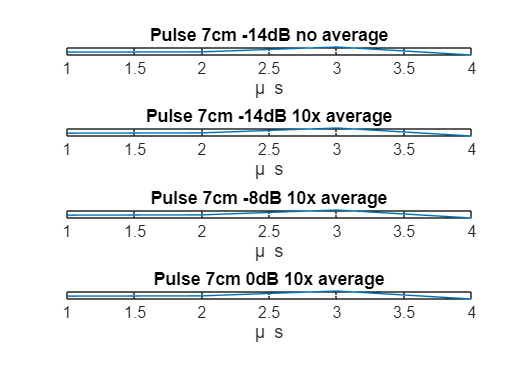

subplot(4,1,1);
plot(pulse_7cm_m14dB_no_aver.Position);
title('Pulse 7cm -14dB no average');
xlabel("\mu s");
ylabel("kPa");

subplot(4,1,2);
plot(pulse_7cm_m14dB_10x_aver.Position);
title('Pulse 7cm -14dB 10x average');
xlabel("\mu s");
ylabel("kPa");

subplot(4,1,3);
plot(pulse_7cm_m8dB_10x_aver.Position);
title('Pulse 7cm -8dB 10x average');
xlabel("\mu s");
ylabel("kPa");

subplot(4,1,4);
plot(pulse_7cm_0dB_10x_aver.Position);
title('Pulse 7cm 0dB 10x average');
xlabel("\mu s");
ylabel("kPa");